# Rock vs No Rock: Data recording sheet

Author: Ross Wilkinson

University: University of Colorado Boulder

## Testing information

- Experiment: Rock vs No Rock

- Objective: Test effect of bicycle lean on maximal power output 

- Date: July 31, 2020

- Location: Locomotion Laboratory

- Subject: UI

- Quarq calibration factor: 278

## Experimental setup

### Protocol reminders

- Charge Garmin, iPad, and IMUs

- Clarify participant understanding and answer questions

- Set saddle height and handlebar position

- Sanitize bicycle

- Calibrate power meter

- Setup cooling fan

- Gift card and signature

### Experimental conditions

- Preferred Lean

- Self-restricted

- Locked

### Trial order

- Warm up: 5 min at ~100 W (3.5 lb)

- Familiarization: Standing and leaning (8.5 lb)

- Pmax Test: 3 x hanging weights under condition 1

- Block 1: Randomize

- Block 2: Randomize

- Block 3: Randomize

### Environmental conditions

- Temperature (C): 21

- Humidity (%): 48

- Pressure (mmHg): 638            

- Altitude (m): 1641

### Subject characteristics

Record subject characteristics to table for group data analysis.

number = 2;
code = {'UI'};
sex = {'M'};
age = 28;
mass = 152; %lb
height = 1.85; %m

T = table(number,code,sex,age,mass,height)

T = 1×6 table
    num     code      sex     age    mass    height
    ___    ______    _____    ___    ____    ______

     2     {'UI'}    {'M'}    28     152      1.85 


## Results

Use mass to calculate individualised hanging weights for Pmax Test.

listPerc = [0.06; 0.12; 0.18];
listHang = listPerc * mass

listHang =     9.1200
   18.2400
   27.3600


### Pmax test

Record Pmax test results. Fit curve to predict optimal hanging weight.

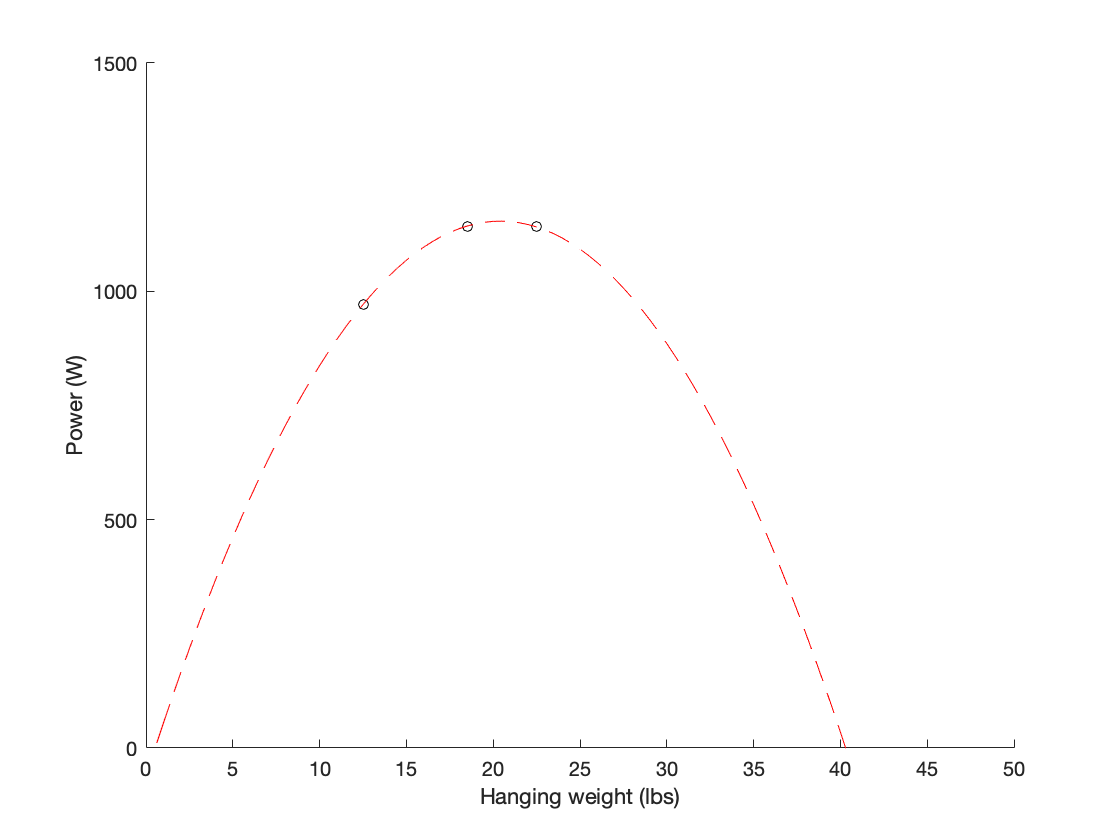

x = [12.5; 18.5; 22.5]; % hanging weight
x_ = [157; 118; 104]; % cadence
y = [971; 1143; 1141]; % power output

% fit curve: power vs hang
% [c, ~, ~] = fit(x,y,'poly2','Lower',[-Inf -Inf 0],'Upper',[Inf Inf 0]);
[c, ~, ~] = fit(x,y,'poly2');

new_x = 0:50/100:50;
new_y = c.p1*new_x.^2+c.p2*new_x+c.p3;

% plot curve: power vs hang
scatter(x,y,25,'k');
hold on
plot(new_x,new_y,'r-')

% edit figure
box off
xlabel('Hanging weight (lbs)')
ylabel('Power (W)')
xlim([0 50])
ylim([0 max(y)*1.2])


% find optimal x and y
[yOpt,I] = max(new_y);
xOpt = new_x(I);

fprintf('Predicted maximal power output = %4.2f Watts \n', yOpt)

Predicted maximal power output = 1153.67 Watts 


fprintf('Predicted optimal hanging weight = %4.2f Lbs \n', xOpt)

Predicted optimal hanging weight = 20.50 Lbs 


### Randomize trial order within each block

randperm(3)

ans =      1     2     3


randperm(3)

ans =      3     2     1


randperm(3)

ans =      2     1     3


### Experimental results

Record results to array then convert to table.

data = [
    2, 1, 1, 20.5, 1033, 111;
    2, 2, 1, 20.5, 1020, 116;
    2, 3, 1, 20.5, 1146, 122;
    2, 2, 2, 20.5, 1079, 120;
    2, 3, 2, 20.5, 1135, 124;
    2, 1, 2, 20.5, 1030, 116;
    2, 3, 3, 20.5, 1168, 123;
    2, 1, 3, 20.5, 1122, 119;
    2, 2, 3, 20.5, 1075, 124;
    ];

T_ = array2table(data, ...
    'VariableNames',{'subject','condition','trial','hangingWeight','power','cadence'})

T_ = 9×6 table
    subject    condition    trial    hangingWeight    power    cadence
    _______    _________    _____    _____________    _____    _______

       2           1          1          20.5         1033       111  
       2           2          1          20.5         1020       116  
       2           3          1          20.5         1146       122  
       2           2          2          20.5         1079       120  
       2           3          2          20.5         1135       124  
       2           1          2          20.5         1030       116  
       2           3          3          20.5         1168       123  
       2           1          3          20.5         1122       119  
       2           2          3          20.5         1075       124  

## Data analysis

Calculate mean and SD power and cadence for experimental trials.

varfun(@mean,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    mean_power    mean_cadence
    _________    __________    __________    ____________

        1            3           1061.7         115.33   
        2            3             1058            120   
        3            3           1149.7            123   


varfun(@std,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    std_power    std_cadence
    _________    __________    _________    ___________

        1            3          52.272        4.0415   
        2            3           32.97             4   
        3            3          16.803             1   
